# First Question 

## `part a,b,c`

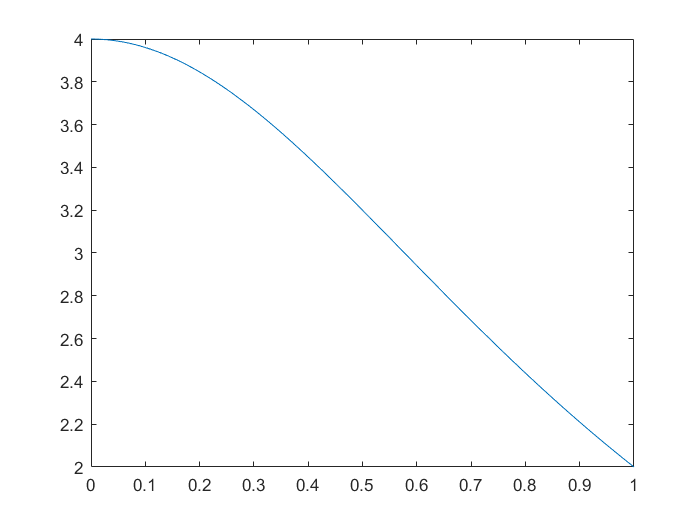

fun = @(x) 4./(1 + x.^2);
start = 0 ;
finish = 1;
sweep = 0:0.01:finish;
plot(sweep,fun(sweep))

## Main Value of integral:

mainInt = vpa(integral(fun,0,1))

$$mainInt = 3.1415926535897932384626433832795$$

## Values of integral evaluated by  MidPoints

midPointInt = zeros(5,1);
for i=1:5
midPointInt(i,1) = midPoint(fun,start,finish,0.1 * i);   
end
midPointInt

midPointInt =     3.1424
    3.1449
    2.9395
    2.7149
    3.1624


## Values of integral evaluated by Trapezoid

trapInt = zeros(5,1);
for i=1:5
trapInt(i,1) = trap(fun,start,finish,0.1 * i);   
end
trapInt

trapInt =     3.1399
    3.1349
    2.8833
    2.5793
    3.1000


## Values of integral evaluated by Simpson

simpsInt = zeros(5,1);
for i=1:5
simpsInt(i,1) = simps(fun,start,finish,0.1 * i);   
end
simpsInt

simpsInt =     3.1416
    3.1416
    2.9208
    2.6697
    3.1416


## Values of integral evaluated by Gauss ( Both methods via 2,3 points )

twoGauss(fun,0,1)

$$ans = 3.1475409836065573770491803278689$$

thirdGauss(fun,0,1)

$$ans = 3.1410681399631675874769797421731$$

midPointIntError = abs(midPointInt - mainInt)

$$midPointIntError = \left(\begin{array}{c} 0.00083333141130458276271423699887048\\ 0.0033332104135345038616018808921198\\ 0.20207752363945553664856521037786\\ 0.42666052689296065927712302128855\\ 0.020760287586677349772650734367556 \end{array}\right)$$

trapIntError = abs(trapInt - mainInt)

$$trapIntError = \left(\begin{array}{c} 0.0016666646826345558123098800182943\\ 0.0066665397788031713970117908660923\\ 0.25832228122066209976863366930217\\ 0.56228230876220703156609165914157\\ 0.041592653589793238462643383279503 \end{array}\right)$$

simpsIntError = abs(simpsInt - mainInt)

$$simpsIntError = \left(\begin{array}{c} 0.00000000062000816736948723529844035272624\\ 0.00000003965057805455793600969395090704\\ 0.22082577616652411290496234698134\\ 0.47186778751604320259624688161916\\ 0.000024026138812846305780638181463669 \end{array}\right)$$

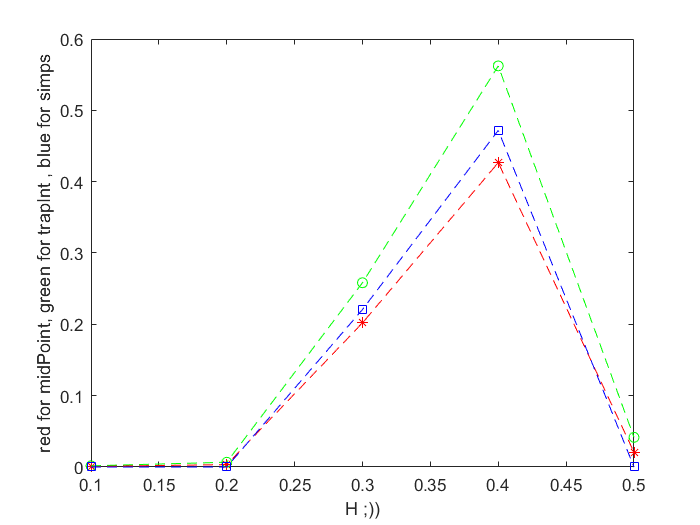

H = 0.1:0.1:0.5;
plot(H,midPointIntError,'r--*',H,trapIntError,'g--o',H,simpsIntError,'--bs');
ylabel('red for midPoint, green for trapInt , blue for simps')
xlabel('H ;))')

`part D`

yes there is a point ...

when we have discontinuity,singularity and immensity around integral boundaries then increasing H will

helps a lot and since we have none of them in this example ...

[just take a look at the first graph ...]  decreasing h yields cause no further improvement...

# Second Question

# Part A

2,3,4 central calculation of Derivative

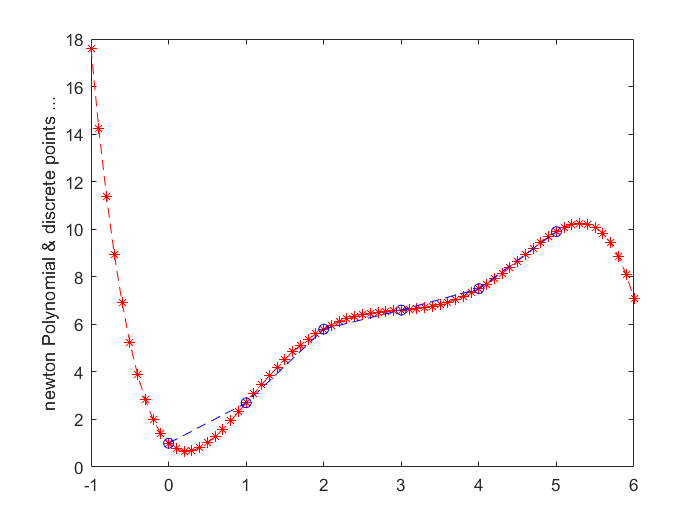

% Main points ...
numberOfPoints = 6;
table = [0,1
         1,2.7
         2,5.8
         3,6.6
         4,7.5
         5,9.9];
syms x     
newton(x) = giveMeNewtonPolynomial(table);
xx = -1:0.1:6;
plot(xx,newton(xx),'r--*');
hold on
plot(table(:,1),table(:,2),'b--o');
ylabel('newton Polynomial & discrete points ...');

% in order to calculate the needed points via interpolation

% 2 points central ... (f(x+h) - f(x-h))/2h
% in order to calculate the derivative of sixth and first element we need to have f(6) and f(-1)
% so I use newton mathod in order to calculate that one 
% an I am allowed by TA : TAHA ASGARI to use this newton for outerpolation ...

centralDeriv2pointMatrix = zeros(numberOfPoints,2);
centralDeriv2pointMatrix(:,1) = table(:,1); 
centralNeeded7thElement =  newton(-1);
centralNeeded8thElement =  newton(6);
for i=1:6
    if(i~=1 && i~=6)
        centralDeriv2pointMatrix(i,2) = (table(i+1,2) - table(i-1,2))/(2*(table(i,1) - table(i-1,1)));   
    else
        if(i == 1)
        centralDeriv2pointMatrix(i,2) = (table(i+1,2) - centralNeeded7thElement)/(2*(table(i+1,1) - table(i,1)));
        else
            if(i==6)
                centralDeriv2pointMatrix(i,2) = (centralNeeded8thElement - table(i-1,2))/(2*(table(i,1) - table(i-1,1)));
            end
        end    
    end    
end


` since we use f(6) and f(-1) to evalaute some derivatives ...`

` absoloutely those which calculated by f(6) and f(-1)--[I mean derivatives at points 0,5 ]--aren't accurate  `

` same as the other points ... soo be careful in this part`

` calculated derivatives in points 1,2,3,4 are more accurate than the other points`

` and as you see the derivatives in 1,2,3,4 are positive and the result matches monotonically increase of`

` Data ...`

centralDeriv2pointMatrix

centralDeriv2pointMatrix =          0   -7.4500
    1.0000    2.4000
    2.0000    1.9500
    3.0000    0.8500
    4.0000    1.6500
    5.0000   -0.2000


%
% in Central method we dont have 3 points formula we just have formulas just for even number of points
%

% 4 points central ... (-f(x+2h) + 8f(x+h) - 8f(x-h) + f(x-2h))/12h
% in order to calculate the derivative of sixth,fifth,first and second elements
% we need to have f(6),f(7),f(-1) and f(-2)
% so I use newton mathod in order to calculate that one 
% an I am allowed by TA : TAHA ASGARI to use this newton for outerpolation ...


centralDeriv4pointMatrix = zeros(numberOfPoints,2);
centralDeriv4pointMatrix(:,1) = table(:,1); 
centralNeeded9thElement =  newton(-2);
centralNeeded10thElement =  newton(7);
for i=1:6
    if(4>=i && i>=3)
        centralDeriv4pointMatrix(i,2) = ((-1)*table(i+2,2) + 8*table(i+1,2) -8*table(i-1,2) + table(i-2,2))/(2*(table(i,1) - table(i-1,1)));   
    else
        if(i == 1)
            centralDeriv4pointMatrix(i,2) = ((-1)*table(i+2,2) + 8*table(i+1,2) -8*centralNeeded7thElement + centralNeeded9thElement)/(2*(table(i+1,1) - table(i,1)));
        else
            if(i == 2)
                     centralDeriv4pointMatrix(i,2) = ((-1)*table(i+2,2) + 8*table(i+1,2) -8*table(i-1,2) + centralNeeded7thElement)/(2*(table(i+1,1) - table(i,1)));
             else
                if(i == 5)
                      centralDeriv4pointMatrix(i,2) = ((-1)*centralNeeded8thElement + 8*table(i+1,2) -8*table(i-1,2) + table(i-2,2))/(2*(table(i+1,1) - table(i,1)));
                else
                    if(i == 6)
                         centralDeriv4pointMatrix(i,2) = ((-1)*centralNeeded10thElement + 8*centralNeeded8thElement -8*table(i-1,2) + table(i-2,2))/(2*(table(i,1) - table(i-1,1)));   
                    end
                end
            end
        end    
       
    end    
end


` since we use f(6) and f(-1) to evalaute some derivatives ...`

` absoloutely those which calculated by f(6),f(7),f(-1) and f(-2)--[I mean derivatives at points 0,1,4,5 ]--aren't accurate  `

` same as the other points ... soo be careful in this part`

` calculated derivatives in points 2,3 are more accurate than the other points`

` and as you see the derivatives in 2,3 are positive and the result matches monotonically increase of`

` Data ...`

centralDeriv4pointMatrix

centralDeriv4pointMatrix =          0  -17.6500
    1.0000   24.7000
    2.0000   12.3500
    3.0000    3.2000
    4.0000   12.5500
    5.0000   13.1000


**Sensitivity to Noise ...**

r = -0.5 + rand(6,1);
noisedPoints(:,1) = table(:,1);
noisedPoints(:,2) = table(:,2) + r

noisedPoints =          0    0.6190
    1.0000    2.6984
    2.0000    6.2597
    3.0000    6.4404
    4.0000    7.5853
    5.0000    9.6238


newtonNoise(x) = giveMeNewtonPolynomial(noisedPoints);
noisecentralDeriv4pointMatrix = zeros(numberOfPoints,2);
noisecentralDeriv4pointMatrix(:,1) = noisedPoints(:,1); 
noisecentralNeeded7thElement =  newtonNoise(-1);
noisecentralNeeded8thElement =  newtonNoise(6);
noisecentralNeeded9thElement =  newtonNoise(-2);
noisecentralNeeded10thElement =  newtonNoise(7);
for i=1:6
    if(4>=i && i>=3)
        noisecentralDeriv4pointMatrix(i,2) = ((-1)*noisedPoints(i+2,2) + 8*noisedPoints(i+1,2) -8*noisedPoints(i-1,2) + noisedPoints(i-2,2))/(2*(table(i,1) - table(i-1,1)));   
    else
        if(i == 1)
            noisecentralDeriv4pointMatrix(i,2) = ((-1)*noisedPoints(i+2,2) + 8*noisedPoints(i+1,2) -8*noisecentralNeeded7thElement + noisecentralNeeded9thElement)/(2*(table(i+1,1) - table(i,1)));
        else
            if(i == 2)
                     noisecentralDeriv4pointMatrix(i,2) = ((-1)*noisedPoints(i+2,2) + 8*noisedPoints(i+1,2) -8*noisedPoints(i-1,2) + noisecentralNeeded7thElement)/(2*(table(i+1,1) - table(i,1)));
             else
                if(i == 5)
                      noisecentralDeriv4pointMatrix(i,2) = ((-1)*noisecentralNeeded8thElement + 8*noisedPoints(i+1,2) -8*noisedPoints(i-1,2) + noisedPoints(i-2,2))/(2*(table(i+1,1) - table(i,1)));
                else
                    if(i == 6)
                         noisecentralDeriv4pointMatrix(i,2) = ((-1)*noisecentralNeeded10thElement + 8*noisecentralNeeded8thElement -8*noisedPoints(i-1,2) + noisedPoints(i-2,2))/(2*(table(i,1) - table(i-1,1)));   
                    end
                end
            end
        end    
       
    end    
end
centralDeriv4pointMatrix

centralDeriv4pointMatrix =          0  -17.6500
    1.0000   24.7000
    2.0000   12.3500
    3.0000    3.2000
    4.0000   12.5500
    5.0000   13.1000


noisecentralDeriv4pointMatrix

noisecentralDeriv4pointMatrix =          0  -29.1302
    1.0000   33.2005
    2.0000   11.4850
    3.0000    1.8394
    4.0000   18.6403
    5.0000   -5.4755


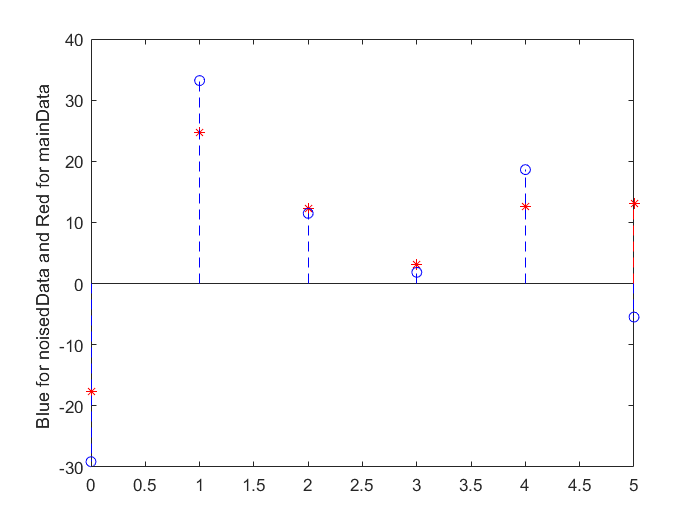

figure
stem(centralDeriv4pointMatrix(:,1),centralDeriv4pointMatrix(:,2),'r--*');
hold on
stem(noisecentralDeriv4pointMatrix(:,1),noisecentralDeriv4pointMatrix(:,2),'b--o');
ylabel('Blue for noisedData and Red for mainData ')

# part B

2,3,4 backward calculation of Derivative

% 2 points backward ... (f(x) - f(x-h))/h
% in order to calculate the derivative of sixth element we need to have f(-1)
% so I use newton mathod in order to calculate that one 
% an I am allowed by TA : TAHA ASGARI to use this newton for outerpolation ...

bakwardDeriv2pointMatrix = zeros(numberOfPoints,2);
bakwardDeriv2pointMatrix(:,1) = table(:,1); 
bakwardNeeded7thElement =  newton(-1);
for i=1:6
    if(i~=1)
        bakwardDeriv2pointMatrix(i,2) = (table(i,2) - table(i-1,2))/(table(i,1) - table(i-1,1));   
    else
        bakwardDeriv2pointMatrix(i,2) = (table(i,2) - bakwardNeeded7thElement)/(table(i,1) - (-1));
    end    
end


`% since we use f(-1) to evalaute some derivatives ...`

`% absoloutely those which calculated by f(-1)--[I mean derivatives at points 0 ]--aren't accurate  `

`% same as the other points ... soo be careful in this part`

`% calculated derivatives in points 1,2,3,4,5 are more accurate than the other points`

` and as you see the derivatives in 1,2,3,4,5 are positive and the result matches monotonically increase of`

` Data ...`

bakwardDeriv2pointMatrix

bakwardDeriv2pointMatrix =          0  -16.6000
    1.0000    1.7000
    2.0000    3.1000
    3.0000    0.8000
    4.0000    0.9000
    5.0000    2.4000


% 3 points ...
% 3 points backward ... (f(x-2h) -4f(x-h) + 3f(x))/2h
% in order to calculate the derivative of sixth element we need to have f(-1) , f(-2) 
% so I use newton mathod in order to calculate that one 
% an I am allowed by TA : TAHA ASGARI to use this newton for outerpolation ...

bakwardNeeded8thElement = newton(-2);
bakwardDeriv3pointMatrix = zeros(numberOfPoints,2);
bakwardDeriv3pointMatrix(:,1) = table(:,1);
for i=1:6
    if(i>2)
        bakwardDeriv3pointMatrix(i,2) = (table(i-2,2) - 4*table(i-1,2) +3*table(i,2))/(2*(table(i,1) - table(i-1,1)));   
    else 
        if(i == 2)
             bakwardDeriv3pointMatrix(i,2) = (bakwardNeeded7thElement - 4*table(i-1,2) -3*table(i,2))/(2*(table(i,1) - table(i-1,1)));   
        else
           if(i == 1)
             bakwardDeriv3pointMatrix(i,2) = (bakwardNeeded8thElement - 4*bakwardNeeded7thElement -3*table(i,2))/(2*(table(i,1) - (-1)));   
           end
        end    
    end    
end


` since we use f(-1),f(-2) to evalaute some derivatives ...`

` absoloutely those which calculated by f(-1) and f(-2) --[I mean derivatives at points 0,1 ]--aren't accurate  `

` same as the other points ... soo be careful in this part`

` calculated derivatives in points 2,3,4,5 are more accurate than the other points`

` and as you see the derivatives in 2,4,5 are positive and the result matches monotonically increase of`

` Data ...`` but as you see derivative in 3 is -0.35 which is negative!(because of this method's error ...  but `

`it's norm is little)`

bakwardDeriv3pointMatrix

bakwardDeriv3pointMatrix =          0    8.1500
    1.0000    2.7500
    2.0000    3.8000
    3.0000   -0.3500
    4.0000    0.9500
    5.0000    3.1500


% 4 points ...
% 4 points forward ... ( 11f(x) - 18f(x-h) + 9f(x-2h) - 2f(x-3h)  )/2h
% in order to calculate the derivative of sixth element we need to have f(-3),f(-2),f(-1)
% so I use newton mathod in order to calculate that one 
% an I am allowed by TA : TAHA ASGARI to use this newton for outerpolation ...
bakwardNeeded9thElement = newton(-3);
bakwardDeriv4pointMatrix = zeros(numberOfPoints,2);
bakwardDeriv4pointMatrix(:,1) = table(:,1);
for i=1:6
    if(i>3)
        bakwardDeriv4pointMatrix(i,2) = ((-2)*table(i-3,2) +9*table(i-2,2) -18*table(i-1,2) +11*table(i,2))/(6*(table(i,1) - table(i-1,1)));   
    else 
        if(i == 3)
             bakwardDeriv4pointMatrix(i,2) = ((-2)*bakwardNeeded7thElement +9*table(i-2,2) -18*table(i-1,2) +11*table(i,2))/(6*(table(i,1) - table(i-1,1)));   
        else
           if(i == 2)
                bakwardDeriv4pointMatrix(i,2) = ((-2)*bakwardNeeded8thElement +9*bakwardNeeded9thElement -18*table(i-1,2) +11*table(i,2))/(6*(table(i,1) - table(i-1,1)));   
           else
               if(i == 1)
                    bakwardDeriv4pointMatrix(i,2) = ((-2)*bakwardNeeded9thElement +9*bakwardNeeded8thElement -18*bakwardNeeded7thElement +11*table(i,2))/(6*(table(i,1) - (-1)));    
               end
           end 
        end    
    end    
end


`% since we use f(-1),f(-2),f(-3) to evalaute some derivatives ...`

`% absoloutely those which calculated by f(-1),f(-2) and f(-3) --[I mean derivatives at points 0,1,2 ]--aren't accurate  `

`% same as the other points ... soo be careful in this part`

`% calculated derivatives in points 3,4,5 are more accurate than the other points`

`and as you see the derivatives in 4,5 are positive and the result matches monotonically increase of`

` Data ...`` but as you see derivative in 3 is -1.5833 which is negative!(because of this method's error)`

bakwardDeriv4pointMatrix

bakwardDeriv4pointMatrix =          0  -10.3833
    1.0000  394.9000
    2.0000   -1.8333
    3.0000   -1.5833
    4.0000    1.7500
    5.0000    3.6167


## Sensitivity to noise ...

bakwardNeeded7thElement = newtonNoise(-1);
noisebackwardNeeded8thElement = newtonNoise(-2);
noisebackwardNeeded9thElement = newtonNoise(-3);
noisebackwardDeriv4pointMatrix = zeros(numberOfPoints,2);
noisebackwardDeriv4pointMatrix(:,1) = noisedPoints(:,1);
for i=1:6
    if(i>3)
        noisebackwardDeriv4pointMatrix(i,2) = ((-2)*noisedPoints(i-3,2) +9*noisedPoints(i-2,2) -18*noisedPoints(i-1,2) +11*noisedPoints(i,2))/(6*(noisedPoints(i,1) - noisedPoints(i-1,1)));   
    else 
        if(i == 3)
             noisebackwardDeriv4pointMatrix(i,2) = ((-2)*bakwardNeeded7thElement +9*noisedPoints(i-2,2) -18*noisedPoints(i-1,2) +11*noisedPoints(i,2))/(6*(noisedPoints(i,1) - noisedPoints(i-1,1)));   
        else
           if(i == 2)
                noisebackwardDeriv4pointMatrix(i,2) = ((-2)*noisebackwardNeeded8thElement +9*noisebackwardNeeded9thElement -18*noisedPoints(i-1,2) +11*noisedPoints(i,2))/(6*(noisedPoints(i,1) - noisedPoints(i-1,1)));   
           else
               if(i == 1)
                    noisebackwardDeriv4pointMatrix(i,2) = ((-2)*noisebackwardNeeded9thElement +9*noisebackwardNeeded8thElement -18*bakwardNeeded7thElement +11*noisedPoints(i,2))/(6*(noisedPoints(i,1) - (-1)));    
               end
           end 
        end    
    end    
end
bakwardDeriv4pointMatrix

bakwardDeriv4pointMatrix =          0  -10.3833
    1.0000  394.9000
    2.0000   -1.8333
    3.0000   -1.5833
    4.0000    1.7500
    5.0000    3.6167


noisebackwardDeriv4pointMatrix

noisebackwardDeriv4pointMatrix =          0  -18.5097
    1.0000  667.8696
    2.0000   -4.9289
    3.0000   -3.1306
    4.0000    3.0753
    5.0000    2.4618


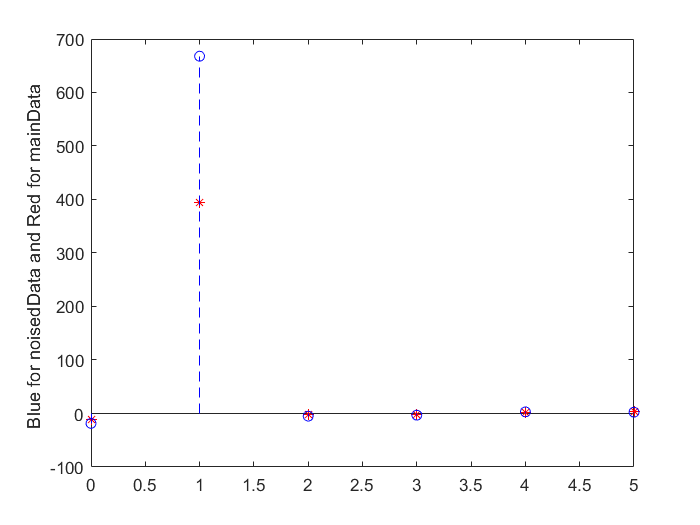

figure
stem(bakwardDeriv4pointMatrix(:,1),bakwardDeriv4pointMatrix(:,2),'r--*');
hold on
stem(noisebackwardDeriv4pointMatrix(:,1),noisebackwardDeriv4pointMatrix(:,2),'b--o');
ylabel('Blue for noisedData and Red for mainData ')

# part C

2,3,4 forward calculation of Derivative

% 2 points forward ... (f(x+h) - f(x))/h
% in order to calculate the derivative of sixth element we need to have f(6)
% so I use newton mathod in order to calculate that one 
% an I am allowed by TA : TAHA ASGARI to use this newton for outerpolation ...
forwardNeeded7thElement =  newton(6);
forwardDeriv2pointMatrix = zeros(numberOfPoints,2);
forwardDeriv2pointMatrix(:,1) = table(:,1);
for i=1:6
    if(i<6)
        forwardDeriv2pointMatrix(i,2) = (table(i+1,2) - table(i,2))/(table(i+1,1) - table(i,1));   
    else
        forwardDeriv2pointMatrix(i,2) = (forwardNeeded7thElement - table(i,2))/( 6 - table(i,1));
    end    
end

` since we use f(6) to evalaute some derivatives ...`

` absoloutely those which calculated by f(6)--[I mean derivatives at points 5 ]--aren't accurate  `

` same as the other points ... soo be careful in this part`

` calculated derivatives in points 0,1,2,3,4 are more accurate than the other points`

`and as you see the derivatives in 0,1,2,3,4 are positive and the result matches monotonically increase of`

` Data ...` 


forwardDeriv2pointMatrix

forwardDeriv2pointMatrix =          0    1.7000
    1.0000    3.1000
    2.0000    0.8000
    3.0000    0.9000
    4.0000    2.4000
    5.0000   -2.8000


% 3 points ...
% 3 points forward ... (-f(x+2h) + 4f(x+h) - 3f(x))/2h
% in order to calculate the derivative of sixth element we need to have f(6),f(7)
% so I use newton mathod in order to calculate that one 
% an I am allowed by TA : TAHA ASGARI to use this newton for outerpolation ...
forwardNeeded8thElement = newton(7);
forwardDeriv3pointMatrix = zeros(numberOfPoints,2);
forwardDeriv3pointMatrix(:,1) = table(:,1);
for i=1:6
    if(i<5)
        forwardDeriv3pointMatrix(i,2) = ((-1)*table(i+2,2) + 4*table(i+1,2) -3*table(i,2))/(2*(table(i+1,1) - table(i,1)));   
    else 
        if(i == 5)
             forwardDeriv3pointMatrix(i,2) = ((-1)*forwardNeeded7thElement + 4*table(i+1,2) -3*table(i,2))/(2*(table(i+1,1) - table(i,1)));   
        else
           if(i == 6)
             forwardDeriv3pointMatrix(i,2) = ((-1)*forwardNeeded8thElement + 4*forwardNeeded7thElement -3*table(i,2))/(2*(6 - table(i,1)));   
           end
        end    
    end    
end


` since we use f(6),f(7) to evalaute some derivatives ...`

` absoloutely those which calculated by f(6) and f(7) --[I mean derivatives at points 4,5 ]--aren't accurate  `

` same as the other points ... soo be careful in this part`

` calculated derivatives in points 0,1,2,3 are more accurate than the other points`

`and as you see the derivatives in 0,1,2,3 are positive and the result matches monotonically increase of`

` Data ...`

forwardDeriv3pointMatrix

forwardDeriv3pointMatrix =          0    1.0000
    1.0000    4.2500
    2.0000    0.7500
    3.0000    0.1500
    4.0000    5.0000
    5.0000   10.7500


% 4 points ...
% 4 points forward ... ( -11f(x) + 18f(x+h) - 9f(x+2h) + 2f(x+3h)  )/2h
% in order to calculate the derivative of sixth element we need to have f(6),f(7),f(8)
% so I use newton mathod in order to calculate that one 
% an I am allowed by TA : TAHA ASGARI to use this newton for outerpolation ...

forwardNeeded9thElement = newton(8);
forwardDeriv4pointMatrix = zeros(numberOfPoints,2);
forwardDeriv4pointMatrix(:,1) = table(:,1);
for i=1:6
    if(i<4)
        forwardDeriv4pointMatrix(i,2) = (2*table(i+3,2) -9*table(i+2,2) +18*table(i+1,2) -11*table(i,2))/(6*(table(i+1,1) - table(i,1)));   
    else 
        if(i == 4)
             forwardDeriv4pointMatrix(i,2) = (2*forwardNeeded7thElement -9*table(i+2,2) +18*table(i+1,2) -11*table(i,2))/(6*(table(i+1,1) - table(i,1)));   
        else
           if(i == 5)
                forwardDeriv4pointMatrix(i,2) = (2*forwardNeeded8thElement -9*forwardNeeded9thElement +18*table(i+1,2) -11*table(i,2))/(6*(table(i+1,1) - table(i,1)));   
           else
               if(i==6)
                    forwardDeriv4pointMatrix(i,2) = (2*forwardNeeded9thElement -9*forwardNeeded8thElement +18*forwardNeeded7thElement -11*table(i,2))/(6*(6 - table(i,1)));    
               end
           end 
        end    
    end    
end


` since we use f(6),f(7),f(8) to evalaute some derivatives ...`

` absoloutely those which calculated by f(6),f(7) and f(8) --[I mean derivatives at points 3,4,5 ]--aren't accurate  `

` same as the other points ... soo be careful in this part`

` calculated derivatives in points 0,1,2 are more accurate than the other points`

`and as you see the derivatives in 0,1,2 are positive and the result matches monotonically increase of`

` Data ...`` but as you see derivative in 0 is -0.2333 which is negative!(because of this method's error)`

`but it's norm is little.`

forwardDeriv4pointMatrix

forwardDeriv4pointMatrix =          0   -0.2333
    1.0000    5.0500
    2.0000    1.2167
    3.0000   -2.0833
    4.0000  194.3500
    5.0000   -3.9833


**Sensitivity to Noise ...**

noiseforwardNeeded7thElement =  newtonNoise(6);
noiseforwardNeeded8thElement = newtonNoise(7);
noiseforwardNeeded9thElement = newtonNoise(8);
noiseforwardDeriv4pointMatrix = zeros(numberOfPoints,2);
noiseforwardDeriv4pointMatrix(:,1) = noisedPoints(:,1);
for i=1:6
    if(i<4)
        noiseforwardDeriv4pointMatrix(i,2) = (2*noisedPoints(i+3,2) -9*noisedPoints(i+2,2) +18*noisedPoints(i+1,2) -11*noisedPoints(i,2))/(6*(noisedPoints(i+1,1) - noisedPoints(i,1)));   
    else 
        if(i == 4)
             noiseforwardDeriv4pointMatrix(i,2) = (2*noiseforwardNeeded7thElement -9*noisedPoints(i+2,2) +18*noisedPoints(i+1,2) -11*noisedPoints(i,2))/(6*(noisedPoints(i+1,1) - noisedPoints(i,1)));   
        else
           if(i == 5)
                noiseforwardDeriv4pointMatrix(i,2) = (2*noiseforwardNeeded8thElement -9*noiseforwardNeeded9thElement +18*noisedPoints(i+1,2) -11*noisedPoints(i,2))/(6*(noisedPoints(i+1,1) - noisedPoints(i,1)));   
           else
               if(i==6)
                    noiseforwardDeriv4pointMatrix(i,2) = (2*noiseforwardNeeded9thElement -9*noiseforwardNeeded8thElement +18*noiseforwardNeeded7thElement -11*noisedPoints(i,2))/(6*(6 - noisedPoints(i,1)));    
               end
           end 
        end    
    end    
end

forwardDeriv4pointMatrix

forwardDeriv4pointMatrix =          0   -0.2333
    1.0000    5.0500
    2.0000    1.2167
    3.0000   -2.0833
    4.0000  194.3500
    5.0000   -3.9833


noiseforwardDeriv4pointMatrix

noiseforwardDeriv4pointMatrix =          0   -0.2826
    1.0000    6.7001
    2.0000   -0.3250
    3.0000   -5.3384
    4.0000  483.6159
    5.0000  -13.3692


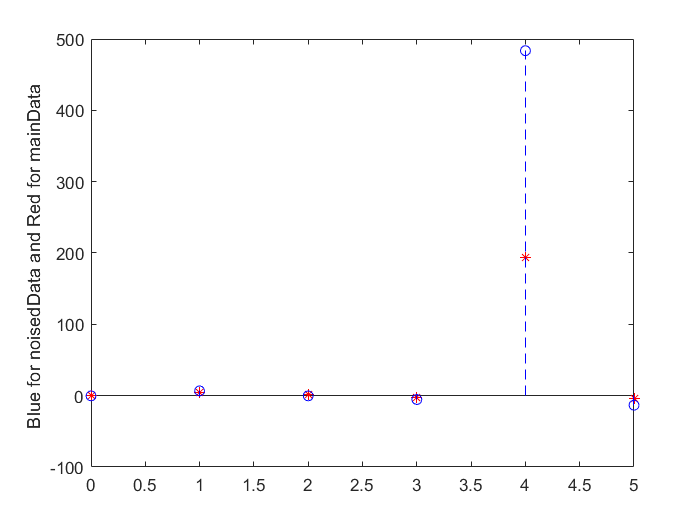


figure
stem(forwardDeriv4pointMatrix(:,1),forwardDeriv4pointMatrix(:,2),'r--*');
hold on
stem(noiseforwardDeriv4pointMatrix(:,1),noiseforwardDeriv4pointMatrix(:,2),'b--o');
ylabel('Blue for noisedData and Red for mainData ')

# Part D

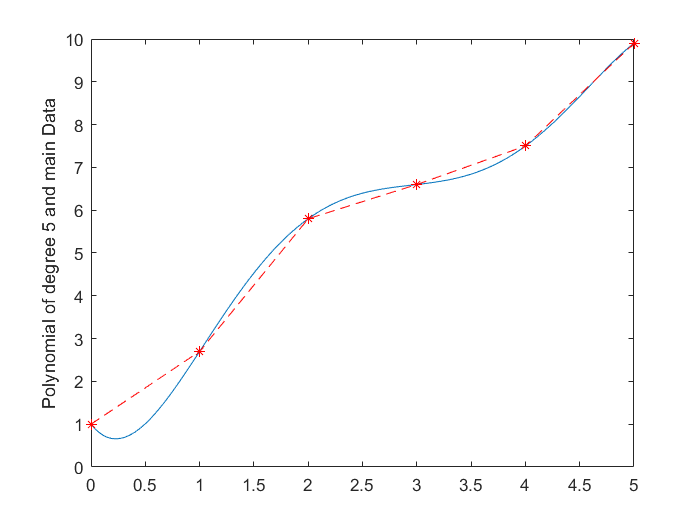

syms x
polyWithDegree5(x) = giveMePolywithDegree(table,5);
Domain = 0:0.01:5;
figure
plot(Domain,polyWithDegree5(Domain));  % it is calculated via least square ...
hold on
plot(table(:,1),table(:,2),'r--*');
ylabel('Polynomial of degree 5 and main Data')

syms x
derivFunction(x) = diff(polyWithDegree5(x))

$$derivFunction(x) = -\frac{42634076468691035\,x^{4}}{144115188075855872}+\frac{238080917782735\,x^{3}}{70368744177664}-\frac{3557140017940047\,x^{2}}{281474976710656}+\frac{4674830237918567\,x}{281474976710656}-\frac{7156970407162217}{2251799813685248}$$

mainDerivs = zeros(numberOfPoints,2);
mainDerivs(:,1) = table(:,1);
for i = 1:6
    mainDerivs(i,2) = derivFunction(mainDerivs(i,1));
end
mainDerivs

mainDerivs =          0   -3.1783
    1.0000    3.8800
    2.0000    1.8217
    3.0000    0.2967
    4.0000    1.8550
    5.0000    1.9467


# Third Question


% consider prey predator problem! below
% derivativeY1 = bY1 - c1Y1Y2
% derivatvieY2 = -dY2 + cY1Y2
%

% differential System Coefficients ...
b = 4;
c1 = -2;
d = 3;
c2 = 3;

%

% As TAHA ASGARI let me ... I changed the coefficients in order to
% get better and beautiful  answer 
% the main Question's given coefficients doesn't give Me a beautiful answer
% so with out losing of generality I changed the coefficients ...
%

% initial values 
y1_0 = 0.5;
y2_0 = 1;

% steps ... 
h = 0.2;
T = 10;

figure % in oreder to draw

syms t y1 y2
derivativeY1(t,y1,y2) = b*y1 + c1*y1*y2;
derivativeY2(t,y1,y2) =  (-1)*d*y2 + c2*y1*y2;

%%%%%%%%%% How to use Methods ...
% if you put Method = 2 it uses second-order Runge-Kutta method 
% and when you use Method = 4 it uses fourth-order RungeKutta method to calculate the answer

% First with the 2 order Method
[Y1_2runge,Y2_2runge] = Runge_kutta(derivativeY1,derivativeY2,y1_0,y2_0,h,T,2);

x =          0    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000    4.2000    4.4000    4.6000    4.8000    5.0000    5.2000    5.4000    5.6000    5.8000    6.0000    6.2000    6.4000    6.6000    6.8000    7.0000    7.2000    7.4000    7.6000    7.8000    8.0000    8.2000    8.4000    8.6000    8.8000    9.0000    9.2000    9.4000    9.6000    9.8000


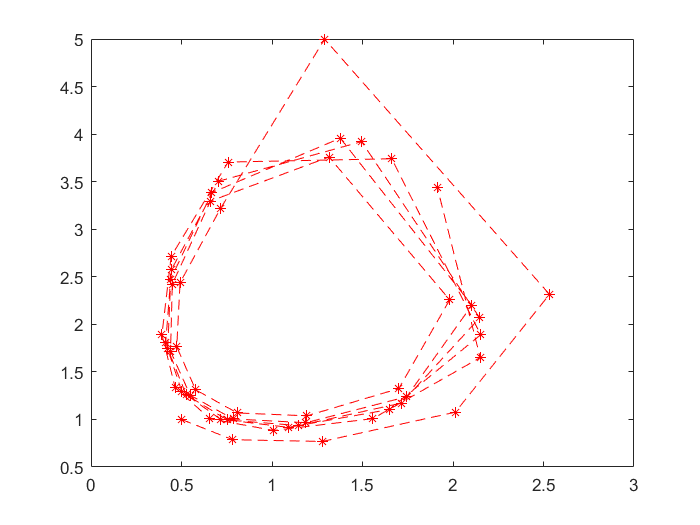

plot(Y1_2runge,Y2_2runge,'r--*')

Y1_2runge

Y1_2runge =     0.5000
    0.7820
    1.2774
    2.0127
    2.5330
    1.2909
    0.7160
    0.4921
    0.4737
    0.5782


Y2_2runge

Y2_2runge =     1.0000
    0.7870
    0.7687
    1.0765
    2.3153
    4.9983
    3.2201
    2.4381
    1.7644
    1.3114


% Second with the 2 order Method
% hold on
[Y1_4runge,Y2_4runge] = Runge_kutta(derivativeY1,derivativeY2,y1_0,y2_0,h,T,4);

x =          0    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000    4.2000    4.4000    4.6000    4.8000    5.0000    5.2000    5.4000    5.6000    5.8000    6.0000    6.2000    6.4000    6.6000    6.8000    7.0000    7.2000    7.4000    7.6000    7.8000    8.0000    8.2000    8.4000    8.6000    8.8000    9.0000    9.2000    9.4000    9.6000    9.8000


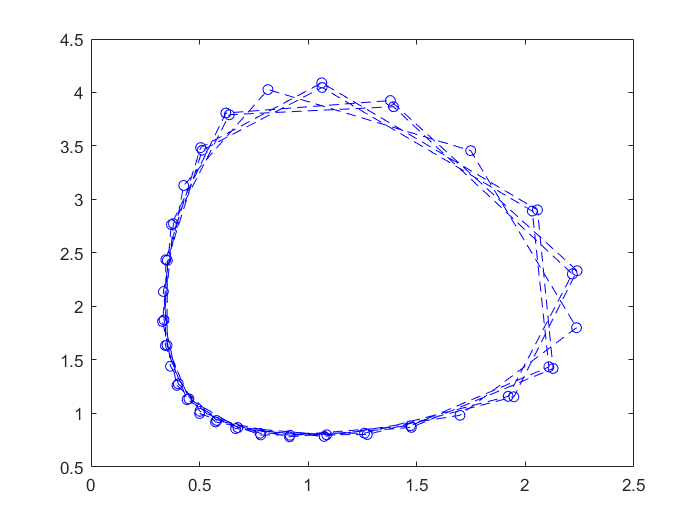

figure
plot(Y1_4runge,Y2_4runge,'b--o')

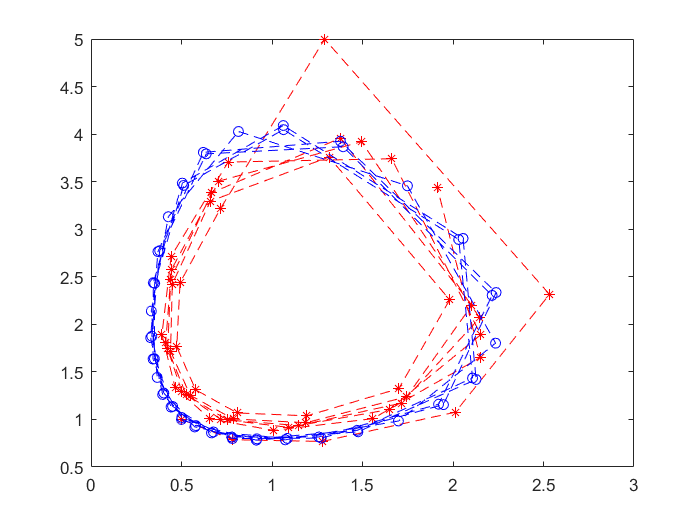

% both graphs in one plot!!!
figure 
plot(Y1_2runge,Y2_2runge,'r--*',Y1_4runge,Y2_4runge,'b--o')

# Fourth Question

% main function 
myFun = @(x) 1./sqrt(1-x.^2);

# part a

mainIntegral = vpa(integral(myFun,-1,1))

$$mainIntegral = 3.1415926535897207294567579083377$$

# part b

` Which of methods between Trapezoid, Midpoint, and Simpson is applicable for this integration? Why?`

**Answer : MidPoint is the key!**

**both simpson and Trapezoid methods need the value of function in both x = -1 , x = 1 **

**but as you see the function in both x = -1 and x = 1 goes into infinity and these values aren't declared in **

**the function's Domain.**

# part c

... use both h = 0.01 and h = 0.001 ...

firstH = midPoint(myFun,-1,1,0.1)

$$firstH = 2.8717612919002304984223817920598$$

firstError = abs(((mainIntegral - firstH)/mainIntegral) * 100)

$$firstError = 8.588999002820087237513406391011$$

secondH = midPoint(myFun,-1,1,0.001)

$$secondH = 3.1145414446888358948443468923793$$

secondError = abs(((mainIntegral - secondH)/mainIntegral) * 100)

$$secondError = 0.86106672263747955914779359917513$$

# part d

 Suggest a strategy for improving accuracy but without the expense of increasing computation intensity ...

**Answer:** `as you know the function is singular arounnd (-1) and (+1)`

`so it is important to have little Hs around these points and`

`average Hs around the other points , and since the function is Even so `

`you can easily calculate integral from -1 to 0 with double precision than -1 to 1 ...`

`also with the same computation intensity ...`

`lets take a look in the graph ...`

figure 
domain = -1 + 0.001:0.001:1 - 0.001

domain =    -0.9990   -0.9980   -0.9970   -0.9960   -0.9950   -0.9940   -0.9930   -0.9920   -0.9910   -0.9900   -0.9890   -0.9880   -0.9870   -0.9860   -0.9850   -0.9840   -0.9830   -0.9820   -0.9810   -0.9800   -0.9790   -0.9780   -0.9770   -0.9760   -0.9750   -0.9740   -0.9730   -0.9720   -0.9710   -0.9700   -0.9690   -0.9680   -0.9670   -0.9660   -0.9650   -0.9640   -0.9630   -0.9620   -0.9610   -0.9600   -0.9590   -0.9580   -0.9570   -0.9560   -0.9550   -0.9540   -0.9530   -0.9520   -0.9510   -0.9500


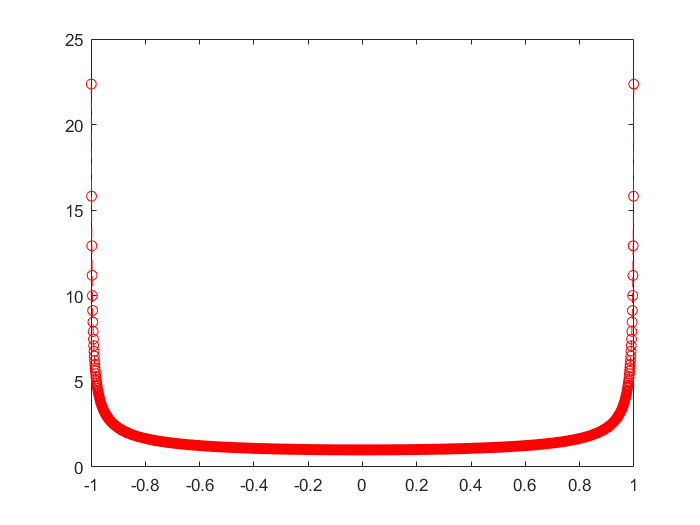

plot(domain,myFun(domain),'r--o');

% now lets do the best!
% you know when H is 0.01 --> number of the calculations is 200 
% we consider this 
% sweep -1 to -0.9 with H = 0.001 --> 100 calculations
% sweep -0.9 to -0.8 with H = 0.005 --> 20 calculation
% sweep 0.8 to 0 with H = 0.01 --> 80 calculation
% then duplicate the calculated integral from -1 to 0 
% in order to calculate the main integral from -1 to 1
improvedOneFirstH = 2* (midPoint(myFun,-1,-0.9,0.001) + midPoint(myFun,-0.9,-0.8,0.005) + midPoint(myFun,-0.8,0,0.01))

$$improvedOneFirstH = 3.0931371683516904946119626685546$$

improvedOneFirstError = abs(((mainIntegral - improvedOneFirstH)/mainIntegral) * 100)

$$improvedOneFirstError = 1.5423859991098109077417033085807$$

% sweep -1 to -0.9 with H = 0.0001 --> 100 calculations
% sweep -0.9 to -0.8 with H = 0.0005 --> 20 calculation
% sweep 0.8 to 0 with H = 0.001 --> 80 calculation
% then duplicate the calculated integral from -1 to 0 
% in order to calculate the main integral from -1 to 1
improvedOneSecondH = 2 * (midPoint(myFun,-1,-0.9,0.0001) + midPoint(myFun,-0.9,-0.8,0.0005) + midPoint(myFun,-0.8,0,0.001))

$$improvedOneSecondH = 3.1309111339523972333264826155999$$

improvedOneSecondError = abs(((mainIntegral - improvedOneSecondH)/mainIntegral) * 100)

$$improvedOneSecondError = 0.34000333000264455394390780861785$$

%                by using myStrategy ...
% when h = 0.01  error decreases from 8.85 to 3.09
% when h = 0.001 error decreases from 0.86 to 0.34

## Functions ....

function midFormula = midPoint(f,start,finish,h)  % first and fourth Question's functions ...
length = floor((finish-start)/h); 
vectors = zeros(1,length); 
for i = 1:length + 1
    vectors(1,i) = start + (i-1) * h;
end
midFormula = vpa(0);
for i = 1:length
   midFormula = midFormula + f((vectors(1,i) +  vectors(1,i+1))/2);
end
midFormula = vpa(midFormula * h);
end



function I = trap(f,a,b,h)
n = floor((b-a)/h);
I =  (f(a) + f(b))/2;
for i = 1:n-1
    I = I + f(a + i*h);
end
I = I * h;
end

function simp = simps(f,a,b,h)
n = floor((b-a)/h);
h2 = h/2;
h3 = f(a+h2);
simp = 0;
for i = 1:n-1
    simp = simp + f(a + i*h);
    h3 = h3 + f(a + i*h + h2);
end
simp = (h/6) * (f(a) + 4*h3 + 2*simp + f(b));
end

function twoPointGauss = twoGauss(f,a,b)
twoPointGauss = vpa(b-a)/2;
first = (-1) * sqrt(3)/3;
second = sqrt(3)/3;
syms x
g(x) = f(0.5*((b-a)*x + (b+a)));
twoPointGauss = twoPointGauss * (vpa(g(first) + g(second)));
end

function thirdPointGauss = thirdGauss(f,a,b)
thirdPointGauss = vpa((b-a)/2);
first = (-1) * sqrt(3/5);
second = 0;
third = sqrt(3/5);
syms x
h(x) = f(0.5*((b-a)*x + (b+a)));
thirdPointGauss = thirdPointGauss * (vpa((1/9)*((5*h(first) + 8*h(second) + 5*h(third)))));
end

%%%%%%%%%%%%%%%%%%%%%% secondQuestion's functions

function f = giveMeNewtonPolynomial(inputValues)
mySize = size(inputValues);
dimension = mySize(1,1);
deltaMatrix  = zeros(dimension,dimension + 1);
deltaMatrix(:,1:2) = inputValues;
for i = 3 : dimension + 1
        temp = 1;
        for k = i-1 : dimension
            deltaMatrix(k,i) = (deltaMatrix(k,i-1) - deltaMatrix(k-1,i-1))/(inputValues(temp + i - 2,1) - inputValues(temp,1));
            temp = temp + 1;
        end
end
% deltaMatrix;
syms x
f(x) = inputValues(1,2) * (x ^ 0);
miniDelta = 1;
for  i=1:dimension-1
miniDelta = (miniDelta)*(x - inputValues(i,1));
f(x) = f(x) + deltaMatrix(i+1,i+2) * miniDelta;
end
f = f(x);
end



function f = giveMePolywithDegree(input,degree)
Mysize = size(input);
m = Mysize(1,1);
sigmaCalculater = zeros(2*degree + 1,1);
sigmaCalculater(1,1) = m;
for power = 1:2*degree
    sum = 0;
    for i=1:m
        sum = sum + input(i,1)^power;
    end
    sigmaCalculater(power + 1,1) = sum;
end

bigMatrixCoef = zeros(degree + 1,degree);
yMat = zeros(degree+1,1);

for i=1:degree + 1
    for j = 1:degree + 1
        bigMatrixCoef(i,j) = sigmaCalculater(i+j-1,1);
    end  
end

for i=1:degree+1
    sum = 0;
    for j=1:m
    sum = sum + (input(j,1)^(i-1))*(input(j,2));
    end
    yMat(i,1) = sum;
end
theCoefs = mldivide(bigMatrixCoef,yMat);
syms x
f(x) = 0*x;
for i=1:degree+1
    f(x) = f(x) + theCoefs(i,1)*(x^(i-1));
end
f = f(x);
end

%%%%%%%%%%%%%%%%%%%%%%% ThirdQuestion's functions ...

function [y1,y2] = Runge_kutta(f1,f2,y1_0,y2_0,h,t,Method)

%%%%%%%%%% How to use Methods ...
% if you put Method = 2 it uses second-order Runge-Kutta method 
% and when you use Method = 4 it uses fourth-order RungeKutta method to calculate the answer

x = 0:h:t
N = length(x);
y1 = zeros(N,1);
y2 = zeros(N,1);

y1(1) = y1_0;
y2(1) = y2_0;

if(Method == 4)
for i = 1:(N-1)  
k1 = h * f1(t,y1(i,1),y2(i,1));
l1 = h * f2(t,y1(i,1),y2(i,1));
k2 = h * f1(t + h/2,y1(i,1) + k1/2 ,y2(i,1) + l1/2);
l2 = h * f2(t + h/2,y1(i,1) + k1/2 ,y2(i,1) + l1/2);
k3 = h * f1(t + h/2,y1(i,1) + k2/2 ,y2(i,1) + l2/2);
l3 = h * f2(t + h/2,y1(i,1) + k2/2 ,y2(i,1) + l2/2);
k4 = h * f1(t + h,y1(i,1) + k3 ,y2(i,1) + l3);
l4 = h * f2(t + h,y1(i,1) + k3 ,y2(i,1) + l3);
y1(i+1) = vpa(y1(i) + (1/6)*(k1 + 2*k2 + 2*k3 + k4));
y2(i+1) = vpa(y2(i) + (1/6)*(l1 + 2*l2 + 2*l3 + l4));
end

else     
if(Method == 2)
for i = 1:(N-1) 
k1 = h * f1(t,y1(i,1),y2(i,1));
l1 = h * f2(t,y1(i,1),y2(i,1));
k2 = h * f1(t + h,y1(i,1) + k1,y2(i,1) + l1);
l2 = h * f2(t + h,y1(i,1) + k1 ,y2(i,1) + l1);
y1(i+1) = vpa(y1(i) + (1/2)*(k1 + k2));
y2(i+1) = vpa(y2(i) + (1/2)*(l1 + l2));
end
end
end
end


